**Simple simulation of the chemostat**

%
% Choose a setup:
%
sSetup = "GeneralistsOnly";
%
% Chemostat parameters:
%
Light = 190;
Mixing = -2.9;
mortHTL = -3;
%
% Run simulation:
%
p = parametersChemostat( eval( strcat('setup',sSetup) ) );

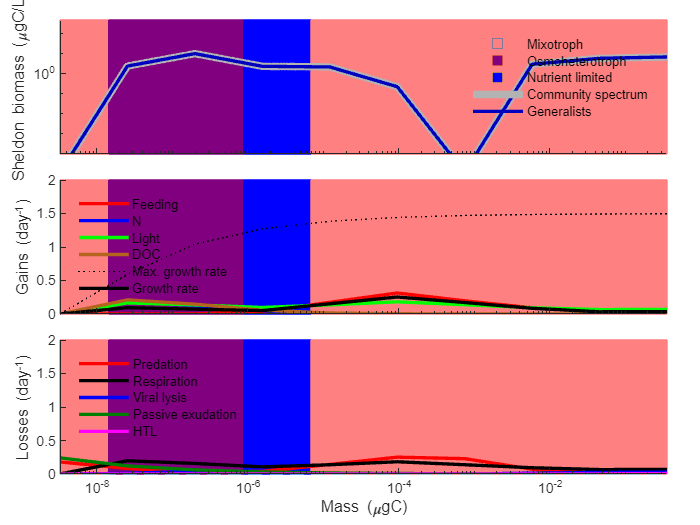

p.tEnd = 1000;

p.d = 10^Mixing;
setHTL(10^mortHTL, 0.05, true, false);

sim = simulateChemostat(p, Light, 10);
%
% Output:
%
plotSizespectrum(sim);

sim = calcFunctions(sim, bPrintSummary=true);

----------------------------------------------
Final total biomass:  1402.149 mgC/m2
Final Chl:               0.774 gChl/m2
Final gross PP:        147.056 mgC/m2/day
Final net PP:            0.000 mgC/m2/day
Final net bact prod.:   61.665 mgC/m2/day
Final HTL production:    2.737 mgC/m2/day
----------------------------------------------


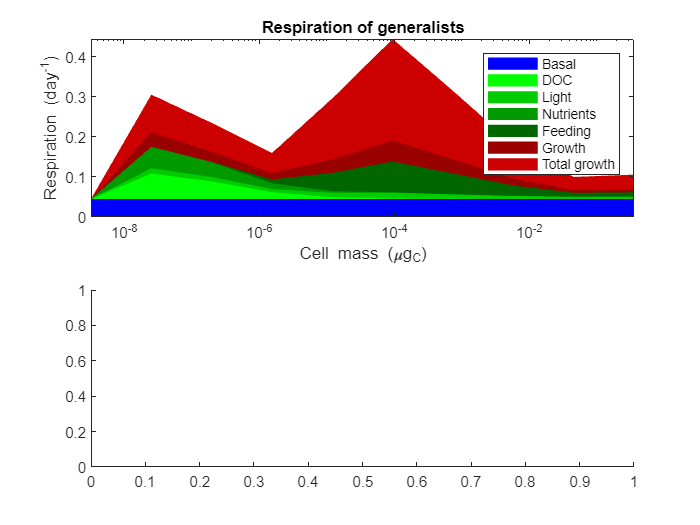

tiledlayout(2,1)
nexttile
panelRespiration(p, sim.rates,1)
nexttile

panelRespiration(p, sim.rates,2)

Index exceeds the number of array elements. Index must not exceed 1.

Error in panelRespiration (line 12)
ix = (p.ixStart(iGroup):p.ixEnd(iGroup))-p.idxB+1;